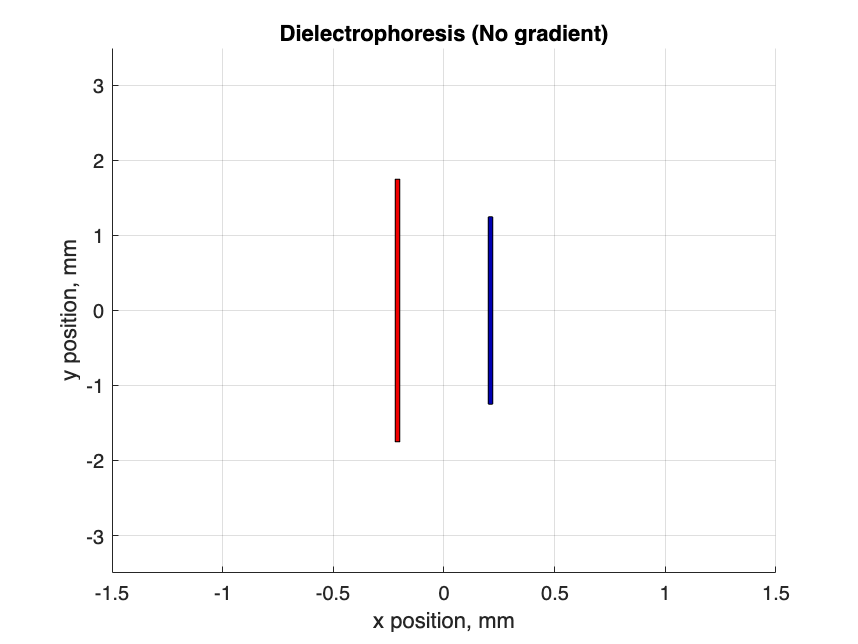

%%%%%%%%%%%%%%%%%%%%%%
%Step0_Session3_F1013B
%%%%%%%%%%%%%%%%%%%%%%

%This template code is very similar to the one you did in the previous 
%challenge session, with some additional lines of code that  
%will warranty that the visualized (plotted) E-field will look good, independently of us
%using the superposition principle to add all contributions to the total
%E-field at each point, or using the gradient of the electric potential to
%calculate the total E-field (also at each point).

%TO-DO%
%Investigate, run, and comment each line, identify the new block(s) of code and
%find out what they do (comment!), this will be part of your Deliverable No. 2.


% Limpieza de variables, ventana de comandos y figuras
clear;      % Limpia todas las variables del espacio de trabajo.
clc;        % Limpia la ventana de comandos.
clf;        % Limpia todas las figuras abiertas.

%----------------- PARÁMETROS INICIALES ------------------%
Lp = 3.5;                     % Longitud del electrodo positivo en mm.
Ln = 2.5;                     % Longitud del electrodo negativo en mm.
t = 0.02;                     % Espesor adicional de los electrodos en mm.
d = 0.4;                      % Distancia entre los electrodos en mm.
p = 0.01;                     % Paso de discretización en mm.

% Características de los electrodos
ke = 1/(4*pi*8.85*10^-12);     % Constante de Coulomb, utilizada para calcular campos eléctricos.
Q = 1e-3;                      % Magnitud de la carga en Coulombs.
Nq = 28;                       % Número de puntos discretos de carga.

%----------------- DEFINICIÓN DEL DOMINIO ------------------%
xmin_original = -d/2 - 3*t;    % Límite inferior original del eje x.
xmax_original = -xmin_original; % Límite superior original del eje x.
xmin = -d/2 - 3*t;             % Límite ajustado del eje x.
xmax = -xmin;                  % Límite ajustado del eje x.
ymin = 2*(-Lp/2);              % Límite inferior del eje y.
ymax = -ymin;                  % Límite superior del eje y.

% Bloque condicional para ajustar los límites si se cumplen ciertas condiciones
if ymin <= -1  
    if xmin >= -0.5 && xmax <= 0.5
        xmin = -1.5;           % Ajusta el límite inferior del eje x a -1.5.
        xmax = -xmin;          % Ajusta el límite superior del eje x a 1.5.
    end
end

% Discretización del dominio
Ny = 30;                       % Número de puntos en el eje y.
Nx = Ny;                       % Número de puntos en el eje x (iguales a Ny).
x = linspace(xmin, xmax, Nx);  % Discretización del eje x en Nx puntos.
y = linspace(ymin, ymax, Ny);  % Discretización del eje y en Ny puntos.

%----------------- GEOMETRÍA DE LOS ELECTRODOS ------------------%
vertices2d = [                 % Coordenadas de los vértices de los electrodos en 2D.
    [-d/2-t, Lp/2]             % Vértice 1 (electrodo positivo)
    [-d/2, Lp/2]               % Vértice 2
    [-d/2, -Lp/2]              % Vértice 3
    [-d/2-t, -Lp/2]            % Vértice 4
    [d/2, Ln/2]                % Vértice 5 (electrodo negativo)
    [d/2+t, Ln/2]              % Vértice 6
    [d/2+t, -Ln/2]             % Vértice 7
    [d/2, -Ln/2]               % Vértice 8
];

facesP = [1 2 3 4 1];          % Conexión de vértices para el electrodo positivo.
facesN = [5 6 7 8 5];          % Conexión de vértices para el electrodo negativo.
colorP = [0.95, 0, 0];         % Color del electrodo positivo (rojo).
colorN = [0, 0, 0.7];          % Color del electrodo negativo (azul).

%----------------- CONFIGURACIÓN DE LA GRÁFICA ------------------%
hold on                        % Permite añadir varios elementos a la gráfica.
axis([xmin xmax ymin ymax])    % Ajusta los límites de los ejes.
xlabel('x position, mm')       % Etiqueta del eje x.
ylabel('y position, mm')       % Etiqueta del eje y.
title('Dielectrophoresis (No gradient)') % Título del gráfico.
grid on                        % Activa la cuadrícula.

% Dibujo de los electrodos
patch('Faces', facesP, 'Vertices', vertices2d, 'FaceColor', colorP); % Dibuja el electrodo positivo.
patch('Faces', facesN, 'Vertices', vertices2d, 'FaceColor', colorN); % Dibuja el electrodo negativo.

Step 1

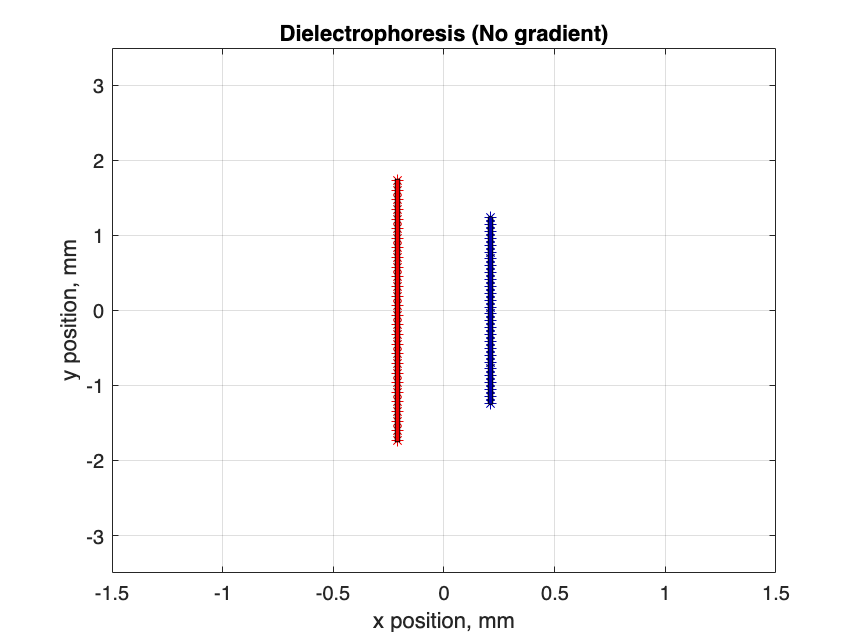

%%%%%%%%%%%%%%%%%%%%%%
%Step1_Session3_F1013B
%%%%%%%%%%%%%%%%%%%%%%

%TO-DO%
%Using the linspace command, and the new template code included here,
%construct a "continuous" electric charge distribution, using a total
%electric charge Q per electrode, and a number of electric charges Nq to
%discretize it.

clear;      % Limpia todas las variables del espacio de trabajo.
clc;        % Limpia la ventana de comandos.
clf;        % Limpia todas las figuras abiertas.

%----------------- PARÁMETROS INICIALES ------------------%
Lp = 3.5;                      % Longitud del electrodo positivo en mm.
Ln = 2.5;                      % Longitud del electrodo negativo en mm.
t = 0.02;                      % Espesor adicional de los electrodos en mm.
d = 0.4;                       % Distancia entre los electrodos en mm.
p = 0.01;                      % Paso de discretización en mm.

% Características de los electrodos
ke = 1/(4*pi*8.85*10^-12);     % Constante de Coulomb, utilizada para calcular campos eléctricos.
Q = 1e-3;                      % Carga total por electrodo en Coulombs.
Nq = 28;                       % Número de puntos discretos de carga.

%----------------- DEFINICIÓN DEL DOMINIO ------------------%
xmin_original = -d/2 - 3*t;    % Límite inferior original del eje x.
xmax_original = -xmin_original; % Límite superior original del eje x.
xmin = -d/2 - 3*t;             % Límite ajustado del eje x.
xmax = -xmin;                  % Límite ajustado del eje x.
ymin = 2*(-Lp/2);              % Límite inferior del eje y.
ymax = -ymin;                  % Límite superior del eje y.

% Bloque condicional para ajustar los límites si se cumplen ciertas condiciones
if ymin <= -1  
    if xmin >= -0.5 && xmax <= 0.5
        xmin = -1.5;           % Ajusta el límite inferior del eje x a -1.5.
        xmax = -xmin;          % Ajusta el límite superior del eje x a 1.5.
    end
end

% Discretización del dominio
Ny = 30;                       % Número de puntos en el eje y.
Nx = Ny;                       % Número de puntos en el eje x (iguales a Ny).
x = linspace(xmin, xmax, Nx);  % Discretización del eje x en Nx puntos.
y = linspace(ymin, ymax, Ny);  % Discretización del eje y en Ny puntos.

%----------------- GEOMETRÍA DE LOS ELECTRODOS ------------------%
vertices2d = [                 % Coordenadas de los vértices de los electrodos en 2D.
    [-d/2-t, Lp/2]             % Vértice 1 (electrodo positivo)
    [-d/2, Lp/2]               % Vértice 2
    [-d/2, -Lp/2]              % Vértice 3
    [-d/2-t, -Lp/2]            % Vértice 4
    [d/2, Ln/2]                % Vértice 5 (electrodo negativo)
    [d/2+t, Ln/2]              % Vértice 6
    [d/2+t, -Ln/2]             % Vértice 7
    [d/2, -Ln/2]               % Vértice 8
];

facesP = [1 2 3 4 1];          % Conexión de vértices para el electrodo positivo.
facesN = [5 6 7 8 5];          % Conexión de vértices para el electrodo negativo.
colorP = [0.95, 0, 0];         % Color del electrodo positivo (rojo).
colorN = [0, 0, 0.7];          % Color del electrodo negativo (azul).

%--------------------- DISTRIBUCIÓN DE CARGAS ------------------%
% Cálculo del diferencial de carga
dq = Q / Nq;                   % Magnitud de cada carga discreta.

% Posiciones de las cargas positivas
yp = linspace(-(1-p)*Lp/2, (1-p)*Lp/2, Nq); % Posiciones Y de las cargas positivas.
xp(1:Nq) = -d/2 - t/2;                      % Posiciones X de las cargas positivas (constante).

% Posiciones de las cargas negativas
yn = linspace(-(1-p)*Ln/2, (1-p)*Ln/2, Nq); % Posiciones Y de las cargas negativas.
xn(1:Nq) = d/2 + t/2;                       % Posiciones X de las cargas negativas (constante).

%--------------------- VISUALIZACIÓN ------------------%
% Verificación de posicionamiento de las cargas
plot(xp, yp, '*', 'Color', colorP);         % Dibuja las posiciones de las cargas positivas.
hold on
plot(xn, yn, '*', 'Color', colorN);         % Dibuja las posiciones de las cargas negativas.

% Configuración de la gráfica
hold on
axis([xmin xmax ymin ymax])    % Ajusta los límites de los ejes.
xlabel('x position, mm')       % Etiqueta del eje x.
ylabel('y position, mm')       % Etiqueta del eje y.
title('Dielectrophoresis (No gradient)') % Título del gráfico.
grid on                        % Activa la cuadrícula.

% Dibujo de los electrodos
patch('Faces', facesP, 'Vertices', vertices2d, 'FaceColor', colorP); % Dibuja el electrodo positivo.
patch('Faces', facesN, 'Vertices', vertices2d, 'FaceColor', colorN); % Dibuja el electrodo negativo.

Step 2

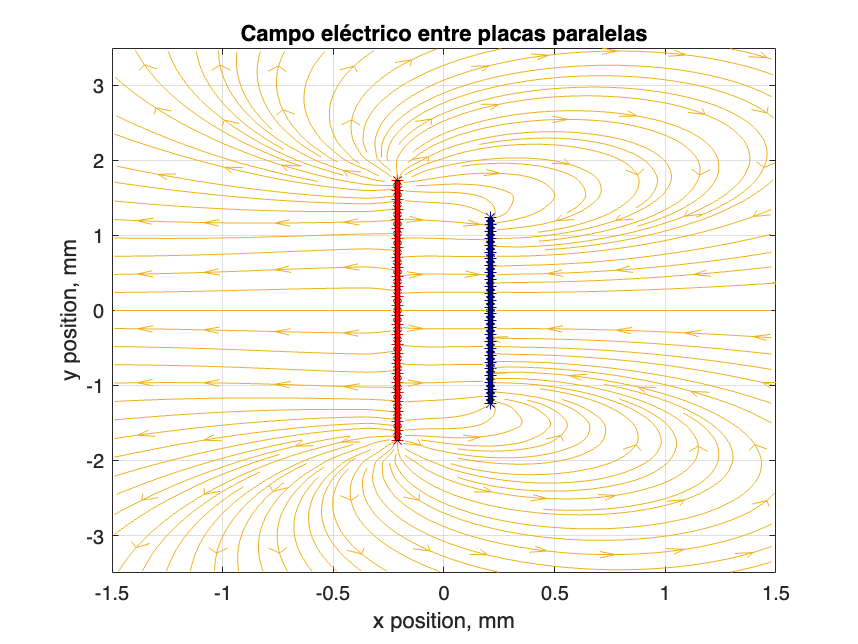

%%%%%%%%%%%%%%%%%%%%%%
%Step2_Session3_F1013B
%%%%%%%%%%%%%%%%%%%%%%

%TO-DO%
%(1) Using three nested for loops, one from i=1:Nx, one from j=1:Ny to cover space, and one from k=1:Nq to cover 
%all charges in the plates, calculate the total electric field inside and around the parallel plates.
%Use the hint code provided, and remember that a single point in space has contributions from each and all 
%electric charges in the plates (i.e. all positive and all negative charges).

%(2) Using a new Matlab command called "streamslice", plot the aforementioned electric field, you already 
% know how does it has to look.

%(3) Test the robustness of you code via changing the Nq, Lp and Ln
%values (what happens with the field lines?) - Expect questions of this
%behavior in your Oral Exam.


clear;
clc;
clf;

%----------------- PARÁMETROS INICIALES ------------------%
Lp = 3.5;                      % Longitud del electrodo positivo en mm.
Ln = 2.5;                      % Longitud del electrodo negativo en mm.
t = 0.02;                      % Espesor adicional de los electrodos en mm.
d = 0.4;                       % Distancia entre los electrodos en mm.
p = 0.01;                      % Paso de discretización en mm.

ke = 1/(4*pi*8.85e-12);        % Constante de Coulomb
Q = 1e-3;                      % Carga total por electrodo en C
Nq = 28;                       % Número de cargas puntuales

%----------------- DEFINICIÓN DEL DOMINIO ------------------%
xmin_original = -d/2 - 3*t;
xmax_original = -xmin_original;
xmin = xmin_original;
xmax = xmax_original;
ymin = 2*(-Lp/2);
ymax = -ymin;

if ymin <= -1  
    if xmin >= -0.5 && xmax <= 0.5
        xmin = -1.5;
        xmax = -xmin;
    end
end

Ny = 30;
Nx = Ny;
x = linspace(xmin, xmax, Nx);
y = linspace(ymin, ymax, Ny);

%----------------- DISTRIBUCIÓN DE CARGAS ------------------%
dq = Q / Nq;

% Cargas positivas
yp = linspace(-(1-p)*Lp/2, (1-p)*Lp/2, Nq);
xp(1:Nq) = -d/2 - t/2;

% Cargas negativas
yn = linspace(-(1-p)*Ln/2, (1-p)*Ln/2, Nq);
xn(1:Nq) = d/2 + t/2;

% Verificación gráfica de las posiciones de las cargas
plot(xp, yp, '*', 'Color', [0.95, 0, 0]);
hold on;
plot(xn, yn, '*', 'Color', [0, 0, 0.7]);

%----------------- CÁLCULO DEL CAMPO ELÉCTRICO ------------------%
Ex = zeros(Nx, Ny);
Ey = zeros(Nx, Ny);

for i = 1:Nx
    for j = 1:Ny
        for k = 1:Nq
            % Positivas
            rxp = x(i) - xp(k);
            ryp = y(j) - yp(k);
            rp = sqrt(rxp^2 + ryp^2)^3;
            Ex(i, j) = Ex(i, j) + ke * dq * rxp / rp;
            Ey(i, j) = Ey(i, j) + ke * dq * ryp / rp;

            % Negativas (ojo con el signo!)
            rxn = x(i) - xn(k);
            ryn = y(j) - yn(k);
            rn = sqrt(rxn^2 + ryn^2)^3;
            Ex(i, j) = Ex(i, j) - ke * dq * rxn / rn;
            Ey(i, j) = Ey(i, j) - ke * dq * ryn / rn;
        end
    end
end

%----------------- VISUALIZACIÓN ------------------%
axis([xmin xmax ymin ymax]);
xlabel('x position, mm');
ylabel('y position, mm');
title('Campo eléctrico entre placas paralelas');
grid on;

% Líneas de campo
streamslice(x, y, Ex', Ey', 2);

%----------------- ELECTRODOS ------------------%
% Electrodo positivo
verticesP = [
    xp(1)-t/2, min(yp);
    xp(1)+t/2, min(yp);
    xp(1)+t/2, max(yp);
    xp(1)-t/2, max(yp)
];

% Electrodo negativo
verticesN = [
    xn(1)-t/2, min(yn);
    xn(1)+t/2, min(yn);
    xn(1)+t/2, max(yn);
    xn(1)-t/2, max(yn)
];

facesP = [1 2 3 4];
facesN = [1 2 3 4];

% Dibujar electrodos
patch('Faces', facesP, 'Vertices', verticesP, 'FaceColor', [0.95, 0, 0]);
patch('Faces', facesN, 'Vertices', verticesN, 'FaceColor', [0, 0, 0.7]);